    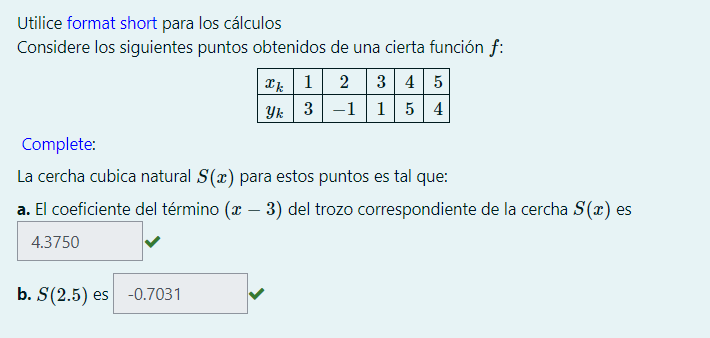

X = [1 2 3 4 5];
Y = [3 -1 1 5 4];

% Los splines cubicos son polinomios de grado 3, por tanto, van de mayor a
% constante

% En cada linea va un ai, bi,ci, di restado menos el i-esimo nodo. 

% Los nodos forman los S_i(x) tramos del spline. En este caso, piden un
% valor de 2.5 que es un numero entre los nodos (2,3); pertenecen al tramo
% de S_1(x) y en la matriz S de matlab es la segunda fila. 

% Al evaluar un spline se hace: valor_evaluar - nodo_tramo para trasladarlo

S=csnatural(X,Y)

S =     1.3750         0   -5.3750    3.0000
   -0.8750    4.1250   -1.2500   -1.0000
   -1.8750    1.5000    4.3750    1.0000
    1.3750   -4.1250    1.7500    5.0000


polyval(S(2,:),2.5-2) 

ans = -0.7031

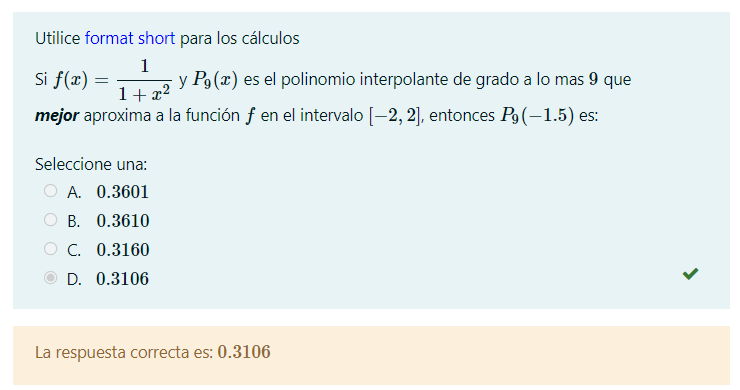


syms x
f = 1/(1+x^2)

$$f = \frac{1}{x^{2}+1}$$

f = matlabFunction(f,'Vars',{x});
[C, X, Y] = cheby (f, 9, -2, 2)

C =     0.4472   -0.0000   -0.3415    0.0000    0.1301    0.0000   -0.0488    0.0000    0.0163    0.0000


X =     1.9754    1.7820    1.4142    0.9080    0.3129   -0.3129   -0.9080   -1.4142   -1.7820   -1.9754


Y =     0.2040    0.2395    0.3333    0.5481    0.9108    0.9108    0.5481    0.3333    0.2395    0.2040


[Cn, D] = newpoly (X, Y)

Cn =    -0.0000    0.0081    0.0000   -0.0894   -0.0000    0.3740    0.0000   -0.7805    0.0000    0.9837


D =     0.2040         0         0         0         0         0         0         0         0         0
    0.2395   -0.1836         0         0         0         0         0         0         0         0
    0.3333   -0.2552    0.1276         0         0         0         0         0         0         0
    0.5481   -0.4243    0.1935   -0.0618         0         0         0         0         0         0
    0.9108   -0.6095    0.1682    0.0172   -0.0475         0         0         0         0         0
    0.9108   -0.0000   -0.4992    0.3864   -0.1762    0.0563         0         0         0         0
    0.5481    0.6095   -0.4992    0.0000    0.1664   -0.1274    0.0637         0         0         0
    0.3333    0.4243    0.1682   -0.3864    0.1664   -0.0000   -0.0399    0.0305         0         0
    0.2395    0.2552    0.1935   -0.0172   -0.1762    0.1274   -0.0399    0.0000    0.0081         0
    0.2040    0.1836    0.1276    0.0618   -0.0475   -0.0563    0.0637   -0.0305    0.0

polyval(Cn,-1.5)

ans = 0.3106

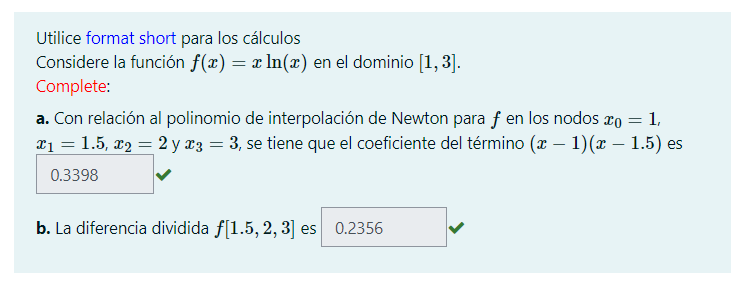

syms x
f = x*log(x)

$$f = x\,\log\left(x\right)$$

f = matlabFunction(f,'Vars',{x});

X = [1 1.5 2 3]

X =     1.0000    1.5000    2.0000    3.0000


Y = f(X)

Y =          0    0.6082    1.3863    3.2958



[Cn, D] = newpoly (X, Y) 

Cn =    -0.0521    0.5743    0.0281   -0.5504


D =          0         0         0         0
    0.6082    1.2164         0         0
    1.3863    1.5562    0.3398         0
    3.2958    1.9095    0.2356   -0.0521


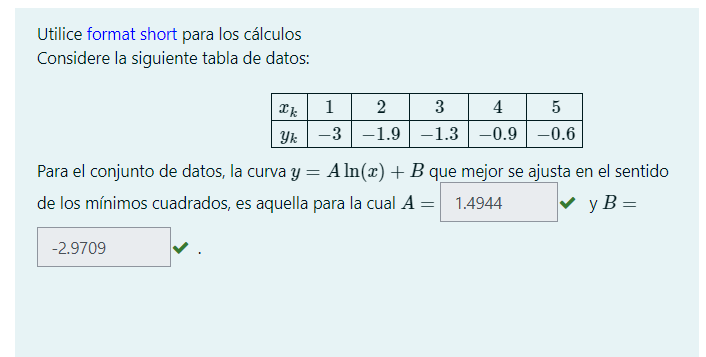

X = [1 2 3 4 5]

X =      1     2     3     4     5


Y = [-3 -1.9 -1.3 -0.9 -0.6]

Y =    -3.0000   -1.9000   -1.3000   -0.9000   -0.6000



XT = log(X);

[A, B] = lsline (XT,Y)

A = 1.4944

B = -2.9709

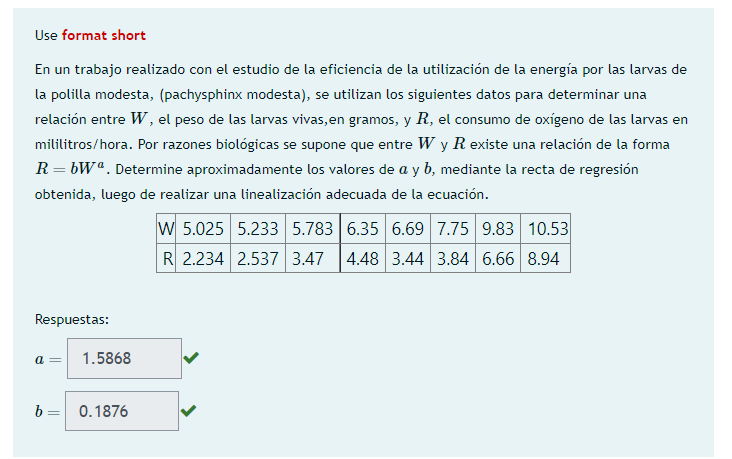

W = [5.025 5.233 5.783 6.35 6.69 7.75 9.83 10.53];
R = [2.234 2.537 3.47 4.48 3.44 3.84 6.66 8.94];

WT = log(W);
RT = log(R);


[A, B] = lsline (WT,RT)

A = 1.5868

B = -1.6734


exp(B)

ans = 0.1876

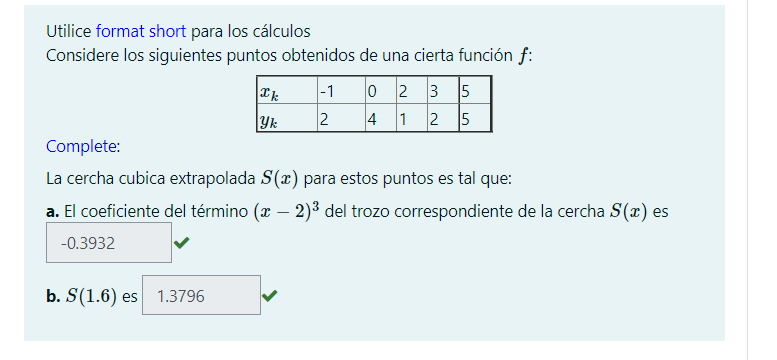

X = [-1 0 2 3 5];
Y = [2 4 1 2 5];

S=csextrapolado(X,Y)

S =     0.5812   -3.4915    4.9103    2.0000
    0.5812   -1.7479   -0.3291    4.0000
   -0.3932    1.7393   -0.3462    1.0000
   -0.3932    0.5598    1.9530    2.0000


polyval(S(2,:),1.6-0)

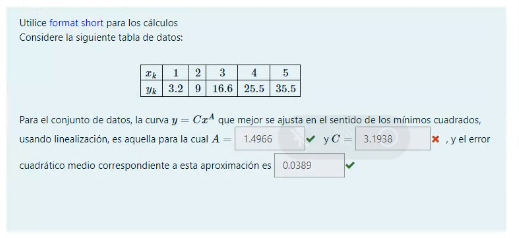

X = [1 2 3 4 5];
Y = [3.2 9 16.6 25.5 35.5];

XT = log(X);
YT = log(Y);
[A, B] = lsline (XT,YT)

A = 1.4966

B = 1.1626


C = exp(B)

C = 3.1983

n=length(X)

n = 5

%YA = polyval([A B],log(X))
%r = exp(YA)
YA = C.*(X.^A)

YA =     3.1983    9.0247   16.5567   25.4658   35.5625


E2medio = sqrt((1/n).*sum((YA-Y).^2))

E2medio = 0.0389